# Homework 4

#### Segmentació

Hem utilitzat la segmentació basada en watershed amb obtenció automàtica de marques. Els passos han sigut:

- Com que la imatge es sorrollosa, primer hem aplicat un filtre open-close a la imatge.

- Tot seguit, per trobar la imatge de marques, hem buscat els màxims regionals.

- Finalment, segmentem la imatge amb watershed sobre la imatge gradient usant els markers obtinguts.

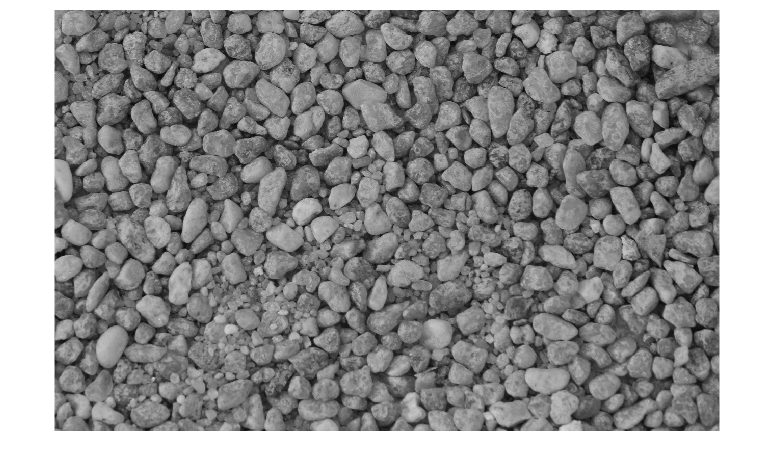

RGB = imread("pedres.jpg");
I = rgb2gray(RGB);
imshow(I);

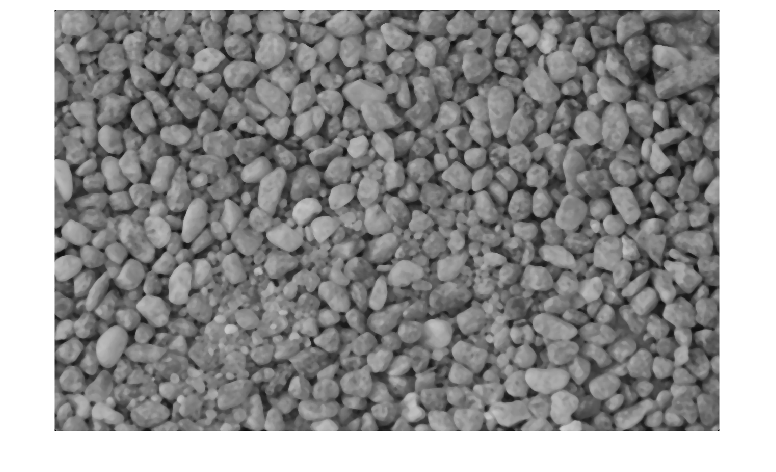


I = medfilt2(I, [7, 7]);
imshow(I);

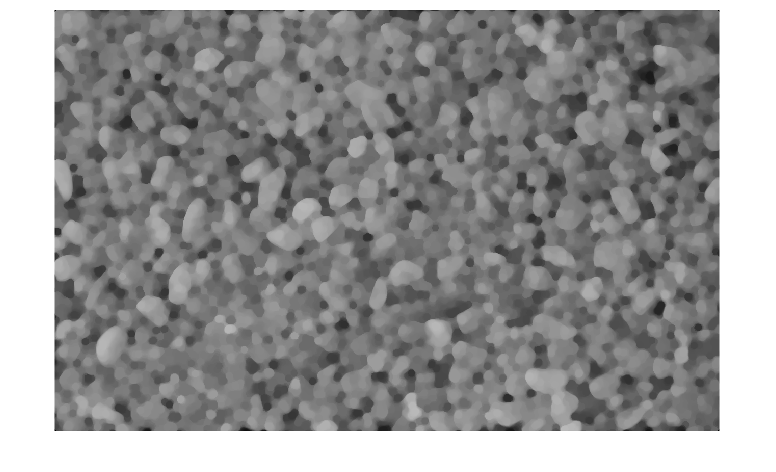


% filtre open-close
SE = fspecial('disk',6) > 0;
IFM = imopen(I,SE);
IFM = imclose(IFM,SE);

imshow(IFM);

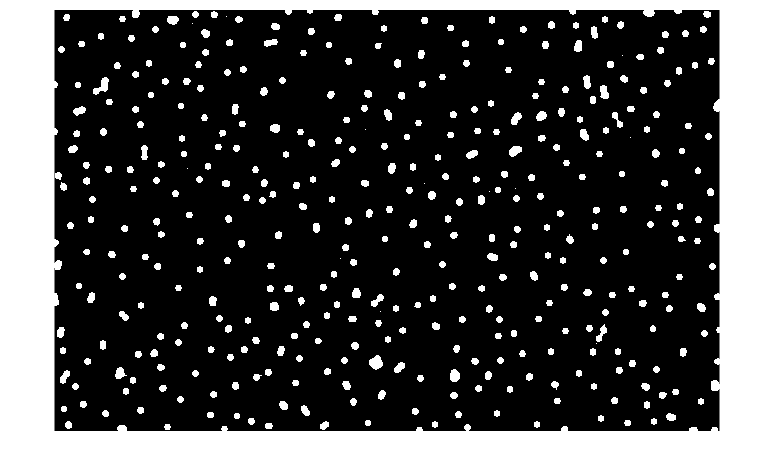


% màxims regionals
IRM = imregionalmax(IFM);

imshow(IRM);

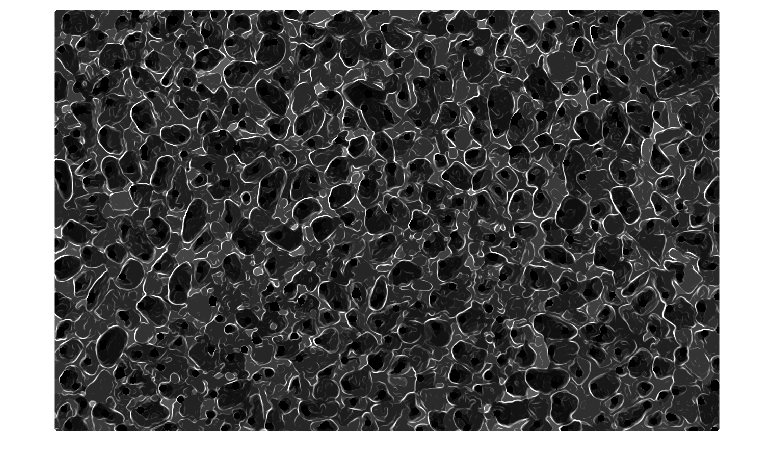


% imatge gradient
Grad = uint8(imgradient(I));
G = imimposemin(Grad, IRM);
imshow(G, []);

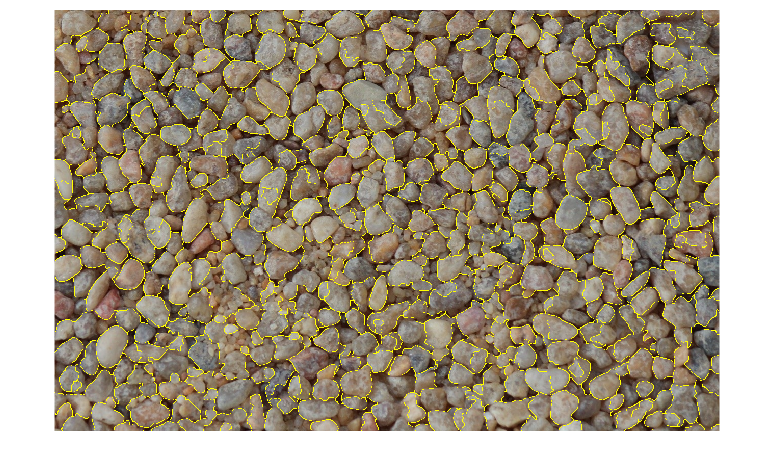


WS = watershed(G);
IB = WS == 0;
RGB_IB = imoverlay(RGB, IB);
imshow(RGB_IB);

#### Número de pedres

Un cop hem segmentat la imatge de pedres, hem de calcular el número de pedres que apareixen. 

Per fer-ho, hem de definir la mida que té una pedra. Nosaltres hem considerat que per ser considerat com una pedra, ha de tenir una mida entre un minSize i un maxSize.

Per trobar aquests llindars, hem buscat el nombre de píxels del component connex més gran, i la t és aquest nombre dividit entre dos. Llavors, el minSize és t menys un offset (4500) i el maxSize és t més un offset (2000). 

FInalment, per calcular el nombre de pedres, hem considerat tots els components connexos que tenen un nombre de píxels entre [minSize, maxSize].

Ens ha donat com a resultat 325 pedres.

CC = bwconncomp(WS);
numObjects = CC.NumObjects;
numPixels = cellfun(@numel,CC.PixelIdxList);
t = max(numPixels) / 2;
minSize = t - 4500;
maxSize = t + 2000;
numPedres = sum(and(numPixels >= minSize,numPixels <= maxSize))

numPedres = 325

#### Pedres residuals

A continuació, podem veure els components connexos que hem descartat, és a dir, aquells que el seu nombre de píxels no es troben entre els llindars. Són o bé pedres massa grans o massa petits.

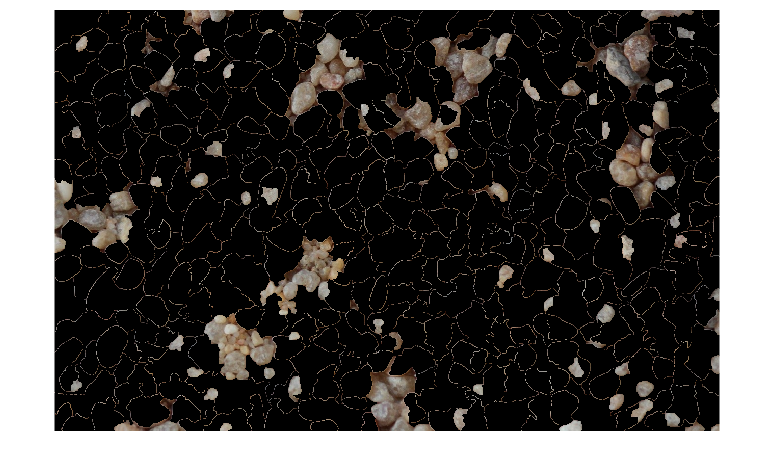

R = WS;
for i=1:numObjects
    if not(and(numPixels(i) >= minSize, numPixels(i) <= maxSize))
        R(CC.PixelIdxList{i}) = 0;
    end
end
IB = R == 0;
imshow(RGB .* uint8(IB));

Autors: Jia Long Ji Qiu, Jiabo Wang

16/04/2023